# Interpolare Hermite

- Să se calculeze $\sin\frac{\pi}{5}$ și $\sin\frac{5\pi}{12}$ folosind interpolarea Hermite cu noduri duble și valorile cunoscute din clasa a VII-a.

- Să se reprezimte pe același grafic funcția și polinomul de interpolare.

- Să se reprezinte grafic eroarea de interpolare.

%1.
% noduri
x=[0,pi/6,pi/4,pi/3,pi/2,pi];
y=sin(x);
yd=cos(x);
%calculăm tabele de diferențe divizate cu noduri duble
[z,T]=divdiffdn(x,y,yd);
t0=[pi/5,5*pi/12];
%aproximantele
z0=Newtonpol(T,z,t0)

z0 =     0.5878    0.9659


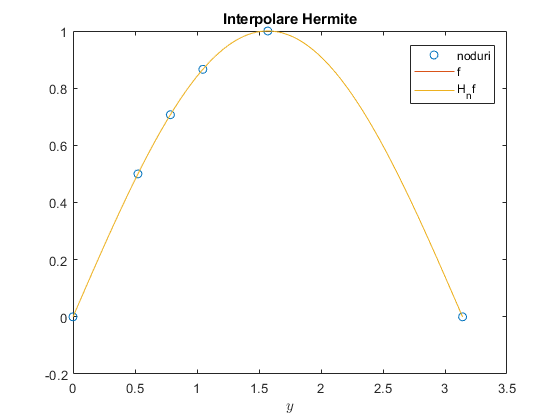

%2. reprezentarea grafica
t=linspace(0,pi,300);
zt=Newtonpol(T,z,t);
plot(x,y,'o',t,sin(t),t,zt)
legend('noduri','f','H_{n}f','Location','best');
xlabel('$x$','Interpreter','Latex')
xlabel('$y$','Interpreter','Latex')
title('Interpolare Hermite')

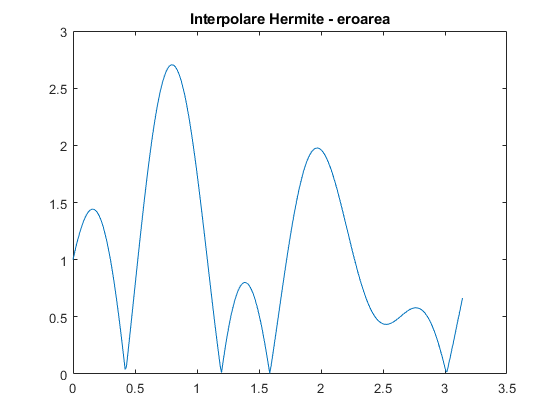

%reprezentarea erorii intr-o figura separata
figure(2)
plot(t,abs(f(t)-zt))
title('Interpolare Hermite - eroarea')